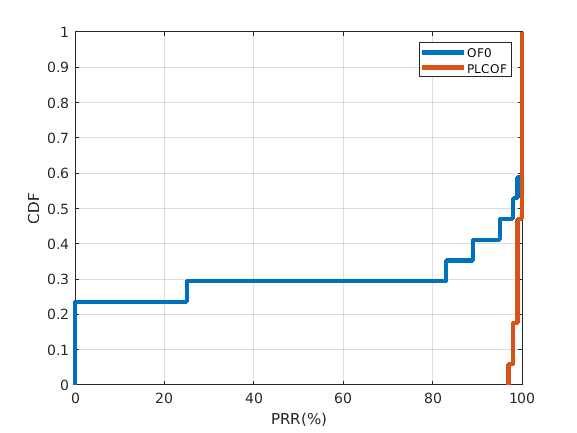

clc;
clear;
sentFile = [
    "OF0_2.dat"
    "PLCOF_2.dat"
    ];

sent_counter = 2;


xlabels = {'OF0','PLCOF'};






for cnt = 1:1:sent_counter
    sent_data(cnt)= {csvread(sentFile(cnt))};
end



sent_array = cell2mat(sent_data);





PRR = [];
diversity = [];
sent_cnt = [];
packet_cnt = [];
for cnt = 1:1:sent_counter
    PRR = [PRR sent_array(:,1 + 4*(cnt-1))];
    diversity = [diversity sent_array(:,4 + 4*(cnt-1))];
    sent_cnt = [sent_cnt sent_array(:,3 + 4*(cnt-1))];
    packet_cnt = [packet_cnt sent_array(:,2 + 4*(cnt-1))];
end

mean_retx = sent_cnt./packet_cnt;
mean_div = diversity ./ packet_cnt;
t = ones(17);
t = t(1,:);
%hold on

prrcdf = cdfplot(PRR(:,1)');
hold on
prrcdf2 = cdfplot(PRR(:,2)');

set(prrcdf, 'LineWidth', 3)
set(prrcdf2, 'LineWidth', 3)
title("")
xlabel("PRR(%)")
ylabel("CDF")
legend('OF0','PLCOF')

hold off
print('PRR','-dpdf')

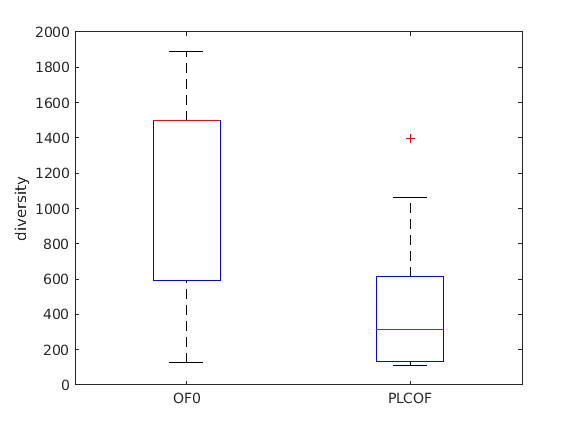


%PRR(:,1)
%cdf = cdf(pd,PRR(:,1)')
%plot(PRR,cdf)


%hold off




boxplot(diversity);
title("")
ylim([0 2000])
xticks([1:2])
xticklabels(xlabels)
ylabel("diversity")
print('Total_diversity','-dpdf')

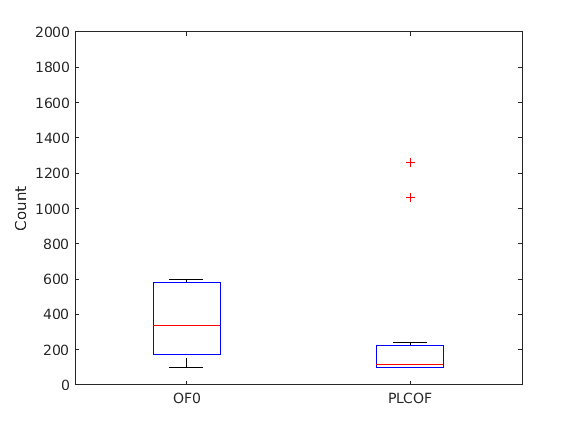




boxplot(sent_cnt);
title("")
ylim([0 2000])
xticks([1:2])
xticklabels(xlabels)
ylabel("Count")
print('Total_sent','-dpdf')


Total_of0 = sum(sent_cnt(:,1))

Total_of0 = 5937

Total_plcof = sum(sent_cnt(:,2))

Total_plcof = 4306

sent_cnt(:,1)

ans =    194
   322
   100
   200
   100
   339
   419
   600
   600
   128


sent_cnt(:,2)

ans =          100
         242
         100
        1258
         100
         104
         100
         101
         101
        1063


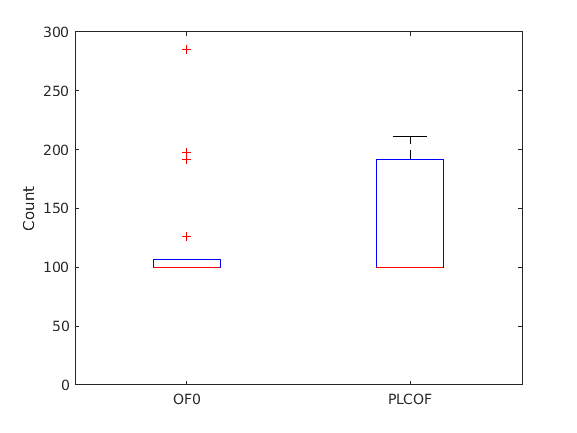




boxplot(packet_cnt);
title("")
ylim([0 300])
xticks([1:2])
xticklabels(xlabels)
ylabel("Count")
print('Total_Packet','-dpdf')

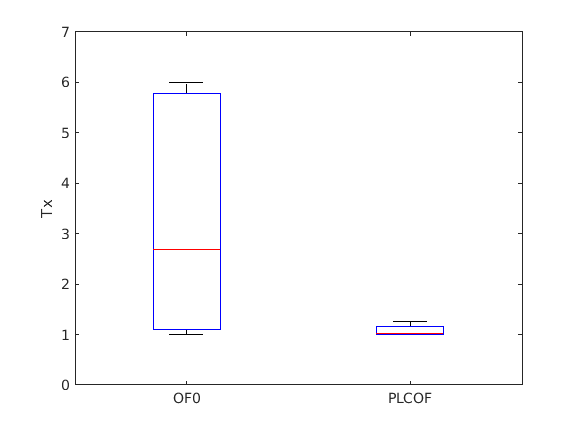


boxplot(mean_retx);
title("")
ylim([0 7])
xticks([1:2])
xticklabels(xlabels)
ylabel("Tx")
print('Mean_TX','-dpdf')

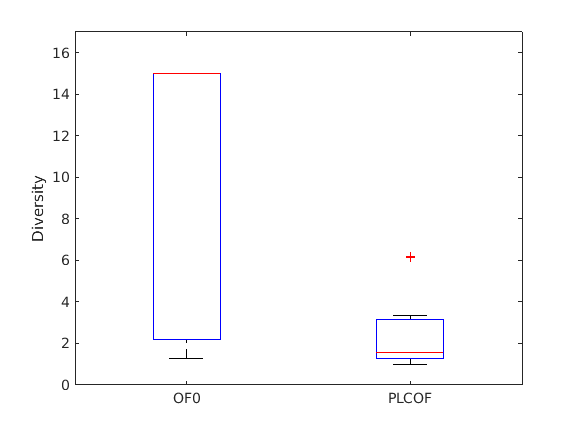


boxplot(mean_div);
title("")
ylim([0 17])
xticks([1:2])
xticklabels(xlabels)
ylabel("Diversity")
print('Mean_diversity','-dpdf')